# Fitting the co-coherence of turbulence with empirical models

The content of this livescript is taken from [1]. The fitting function and its variations have also been sued in refs. [4,5,6]

## Definitions and background

The coherence is a correlation function in the frequency space used to describe the spatial structure of wind turbulence. The square-root of the coherence is named root-coherence. The root-coherence is a complex-valued function, the real part of which is often named co-coherence and denoted $\gamma_{ij}$. Its imaginary part, called quad-coherence, is denoted $\rho_{ij}$


$$\mathrm{coh}_{i} (f,d_x,d_y,d_z)  = \gamma_{i} (f,d_x,d_y,d_z) + i \rho_{i} (f,d_x,d_y,d_z)$$


The co-coherence has been used since the 1960s to model the dynamic wind load on large wind-sensitive structures.

For vertical separations, the co-coherence is defined as:


$$ \gamma_{i} (z_1,z_2,f)  = \frac{\mathrm{Re}\left\lbrace S_{i}(z_1,z_2,f)\right \rbrace}{\sqrt{S_{i}(z_1,f)S_{i}(z_2,f)}} $$


where $S_{i}(z_1,z_2,f)$ is the cross-spectral density of the $i = \lbrace u, v, w \rbrace$  velcity components between heights $z_1$ and $z_{2\;}$; $S_{i}(z_1,f)$ is the single-point spectrum of the $i$ component measured at $z_1$ and$S_{i}(z_2,f)$ is the single-point spectrum of the $j$ component measured at $z_2$.

### Case of a lateral separation with non-zero yaw angle

If two anemometers are at the same height but that the yaw angle is not zero, the flow is skewed. In that case, the along-wind separation is not zero. The co-coherence has to be multiplied with a cosine term as follows


$$\gamma_{j}(d_x,d_y,f)  \cdot \cos\left(2 \pi \frac{fd_x }{\overline{u}} \right) $$


where $d_x
$ is the along-wind sepratation.

### Empirical co-coherence models

For vertical separatio or lateral separation with zero yaw angle ($d_x = 0
$), the Davenport coherence model [1] can be used to approximate the co-coherence.  The Davenport model is one of the first empirical model used to describe the vertical co-coherence. For $i = \left\lbrace u,v,w \right\rbrace$, it is defined as:

$\gamma_{ii}(z_1,z_2,f)  = \exp\left(-\frac{c^{i}_{z}f |z_1 - z_2|}{\overline{u}(z_1,z_2)}\right) $ (1)


$$\overline{u}(z_1,z_2)  = \frac{1}{2} \left[\overline{u}\left(z_1\right) + \overline{u}\left(z_2\right)\right]$$


where $c^{i}_{z}$ is a constant called exponential decay and  $z_1$ and $z_2$ are two measurement heights. 

At a height below 40 m above the surface, a possible dependency of the exponential decay $c^{i}_{z}$ with the measurement height and separation distance has been documented in Bowen et al. [3]. This dependency may reflect the increasing size of the turbulent eddies with the altitude and the blockage by the surface [1,3]. Bowen et al. [3] proposed, therefore,  $c^{i}_{z} = c^i_1 + 2 c^i_2 d_z/\left(z_1+z_2\right)$. This formula can also be extended to lateral separations. The so-called Bowen co-coherence model is:

$\gamma_{i}(z_1,z_2,f)  = \exp\left(-\frac{c^{i}_{1}f|z_2-z_1|}{\overline{u}(z_1,z_2)}\right)\exp\left(-\frac{2c^{i}_{2}f|z_2-z_1|^2}{\left(z_1+z_2\right)\overline{u}(z_1,z_2)}\right)$ (2)

This equation shows that sufficiently far from the surface, the Bowen model can be approximated by the Davenport model.  In Cheynet [1], the Bowen model was modified to include an additional decay parameter $c^{i}_3$, which accounts for the limited size of the eddies, such that the coherence cannot be equal to unity at zero frequency. This leads to the modified Bowen model [1]

$ \gamma_{ii}(z_1,z_2,f)  = \exp\left\lbrace -\left[\frac{|z_2-z_1|}{\overline{u}(z_1,z_2)}\sqrt{(c^{i}_{1} f)^{2} +(c^{i}_{3})^2}\right]\right\rbrace \exp\left(-\frac{2 c^{i}_{2}f|z_2-z_1|^2}{\left(z_1+z_2\right)\overline{u}(z_1,z_2)}\right) $ (3)

The present script use the lsqcurvefit functions to fit equations (1)-(3) to an target co-coherence estimate. Since the co-coherence depends both on the distance and the frequency, the fitting procedure is a surface fitting.

### **References**

[1] Cheynet, Etienne. "Influence of the measurement height on the vertical coherence of natural wind." *Conference of the Italian Association for Wind Engineering*. Springer, Cham, 2018.

[2] Davenport, Alan G. "The response of slender, line-like structures to a gusty wind." *Proceedings of the Institution of Civil Engineers* 23.3 (1962): 389-408.

[3] Bowen, A. J., R. G. J. Flay, and H. A. Panofsky. "Vertical coherence and phase delay between wind components  in strong winds below 20 m." *Boundary-Layer Meteorology* 26.4 (1983): 313-324.

[4] Cheynet, Etienne, Jasna B. Jakobsen, and Joachim Reuder. "Velocity  spectra and coherence estimates in the marine atmospheric boundary  layer." *Boundary-layer meteorology* 169.3 (2018): 429-460.

[5] Cheynet, Etienne, et al. "The COTUR project: remote sensing of offshore turbulence for wind energy application." *Atmospheric Measurement Techniques* 14.9 (2021): 6137-6157.

[6] Midjiyawa, Zakari, et al. "Potential  and challenges of wind measurements using met-masts in complex  topography for bridge design: Part II–Spectral flow characteristics." *Journal of Wind Engineering and Industrial Aerodynamics* 211 (2021): 104585.

## Case of idealized data

clearvars;close all;clc;

z = [10 20 30 50 100]; % Different heights above ground
U = log(z./0.03); % mean wind speed profile

Nm = numel(z);

[d,indZ] = getDistance(z);

% Get average height and wind speed
meanZ = zeros(size(indZ,1),1);
meanU = zeros(size(indZ,1),1);
for ii=1:size(indZ,1)
    meanZ(ii) = 0.5.*(z(indZ(ii,1))+z(indZ(ii,2))');
    meanU(ii) = 0.5.*(U(indZ(ii,1))+U(indZ(ii,2))');
end

% Frequency vector
f = logspace(log10(1/600),log10(1),100);



###  Example 1: Fit the Davenport model to the target coherence 

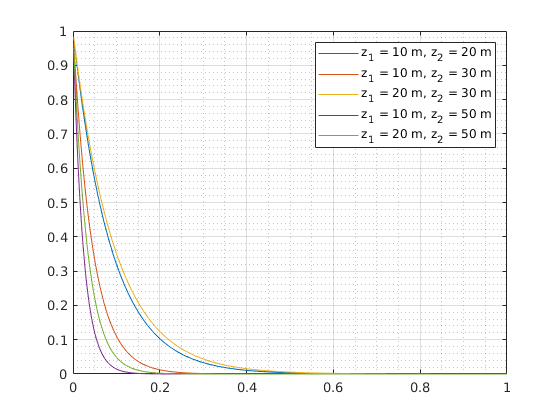

C = [7 0 0]; % Davenport model

cohType = 'Davenport';

[cohU] = targetCoh(meanU,d,f,meanZ,C,cohType);

clear leg
clf;close all;
figure
for ii=1:Nm
    plot(f,cohU(ii,:));hold on;
    leg{ii} = ['z_1 = ',num2str(z(indZ(ii,1))),' m, z_2 = ',num2str(z(indZ(ii,2))),' m'];
    grid on
    grid minor
end
legend(leg{:})

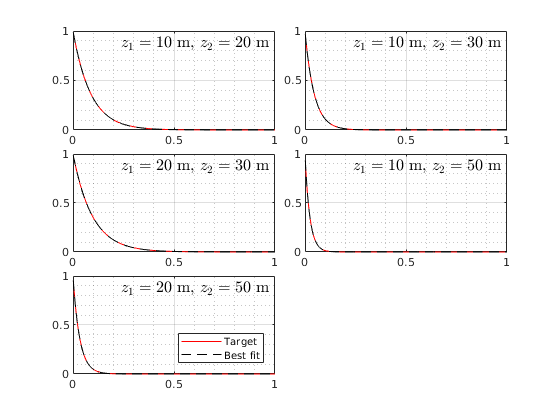



guess = 5;
[CoeffFit,modelFun] = cohFit(d,f,cohU,guess,meanU,'freqThres',0.2);
clear leg
clf;close all;
figure
tiledlayout('flow','tilespacing','none')
for ii=1:Nm
    nexttile
    plot(f,cohU(ii,:),'r');hold on;
    plot(f,modelFun(CoeffFit,f,d(ii),meanZ(ii),meanU(ii),0),'k--')
    txt = ['$z_1 = ',num2str(z(indZ(ii,1))),'$ m, $z_2 = ',num2str(z(indZ(ii,2))),'$ m'];
    label(txt,0.97,0.97,'alignement','right','verticalalignment','top');
    grid on
    grid minor
    
end
legend('Target','Best fit','location','southeast')

###  Example 2: Fit the Bowen model to the target coherence 

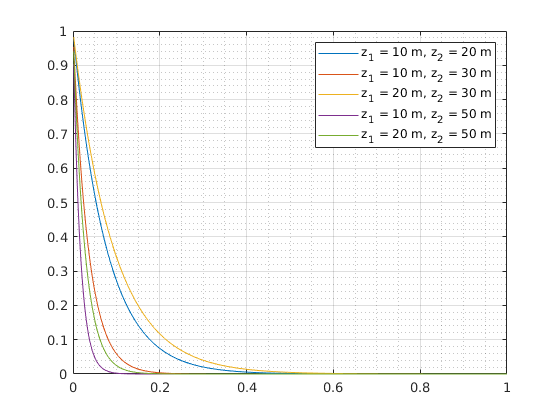

C = [6 3 0]; % Bowen model
cohType = 'Bowen';

[cohU] = targetCoh(meanU,d,f,meanZ,C,cohType);

clear leg
clf;close all;
figure
for ii=1:Nm
    plot(f,cohU(ii,:));hold on;
    leg{ii} = ['z_1 = ',num2str(z(indZ(ii,1))),' m, z_2 = ',num2str(z(indZ(ii,2))),' m'];
    grid on
    grid minor
end
legend(leg{:})

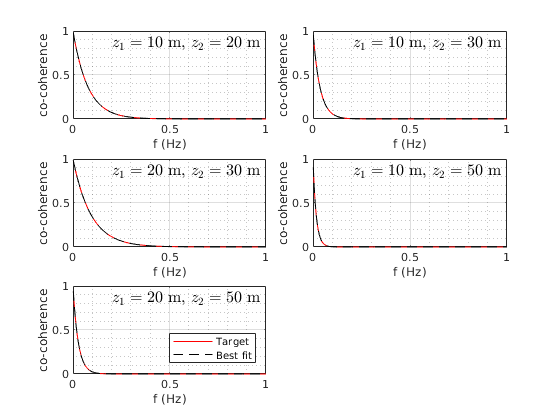


guess = [5 5]; % 2 parameters for the Bowen model
% Note that we need one more argument with the Bowen model, which is the
% average height Z
[CoeffFit,modelFun] = cohFit(d,f,cohU,guess,meanU,'freqThres',0.2,'cohModel','Bowen','z',meanZ);
clear leg
clf;close all;
figure
tiledlayout('flow','tilespacing','none')
for ii=1:Nm
    nexttile
    plot(f,cohU(ii,:),'r');hold on;
    plot(f,modelFun(CoeffFit,f,d(ii),meanZ(ii),meanU(ii),0),'k--')
    txt = ['$z_1 = ',num2str(z(indZ(ii,1))),'$ m, $z_2 = ',num2str(z(indZ(ii,2))),'$ m'];
    label(txt,0.97,0.97,'alignement','right','verticalalignment','top');
    grid on
    grid minor
    xlabel('f (Hz)')
    ylabel('co-coherence')
end
legend('Target','Best fit','location','southeast')

###  Example 3: Fit the modified Bowen model to the target coherence 

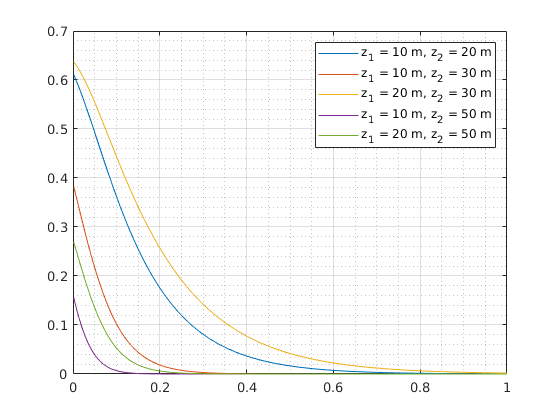

C = [3 3 0.3]; % Modified Bowen model
cohType = 'Bowen2';

[cohU] = targetCoh(meanU,d,f,meanZ,C,cohType);

clear leg
clf;close all;
figure
for ii=1:Nm
    plot(f,cohU(ii,:));hold on;
    leg{ii} = ['z_1 = ',num2str(z(indZ(ii,1))),' m, z_2 = ',num2str(z(indZ(ii,2))),' m'];
    grid on
    grid minor
end
legend(leg{:})

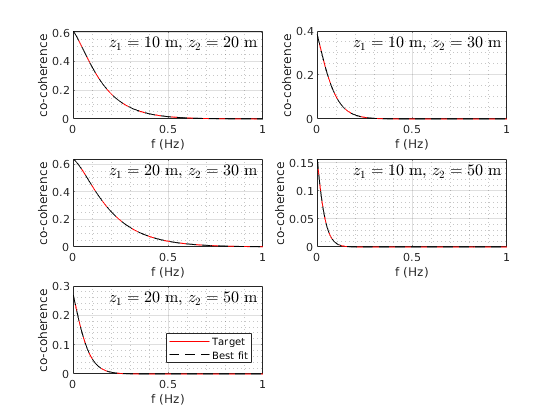


guess = [5 5 0.01]; % 2 parameters for the Bowen model
% Note that we need one more argument with the Bowen model, which is the
% average height Z
[CoeffFit,modelFun] = cohFit(d,f,cohU,guess,meanU,'freqThres',0.2,'cohModel','Bowen2','z',meanZ);
clear leg
clf;close all;
figure
tiledlayout('flow','tilespacing','none')
for ii=1:Nm
    nexttile
    plot(f,cohU(ii,:),'r');hold on;
    plot(f,modelFun(CoeffFit,f,d(ii),meanZ(ii),meanU(ii),0),'k--')
    txt = ['$z_1 = ',num2str(z(indZ(ii,1))),'$ m, $z_2 = ',num2str(z(indZ(ii,2))),'$ m'];
    label(txt,0.97,0.97,'alignement','right','verticalalignment','top');
    grid on
    grid minor
    xlabel('f (Hz)')
    ylabel('co-coherence')
end
legend('Target','Best fit','location','southeast')

###  Fit the Davenport model with lateral separation and non-zero yaw angle 

The cosine term comes from non-zero yaw angle between two anemometers at the same height, for example. Here, Taylor's frozen turbulence hypothesis is assumed valid.

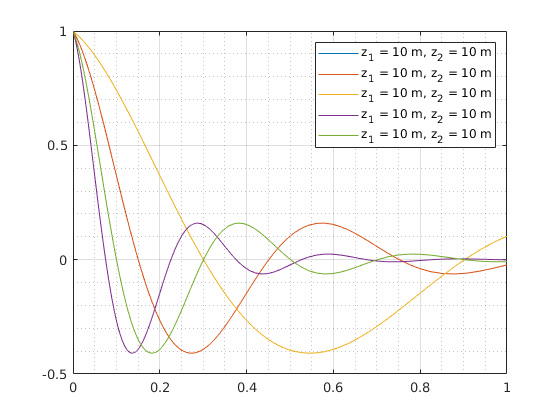

clearvars;close all;clc;

yaw = 75; % yaw angle of 75 deg
y = [0 5 10 20 30]; % Different heights above ground
z = 10.*ones(size(y)); % Same height everywhere
U = log(z./0.03); % mean wind speed profile



Nm = numel(z);
[dx] = getDistance(y.*sind(yaw));
[dy,indZ] = getDistance(y.*cosd(yaw));
if isempty(dy), dy = zeros(size(dx)); end
if isempty(dx), dx = zeros(size(dy)); end
% Get average height and wind speed
meanZ = zeros(size(indZ,1),1);
meanU = zeros(size(indZ,1),1);
for ii=1:size(indZ,1)
    meanZ(ii) = 0.5.*(z(indZ(ii,1))+z(indZ(ii,2))');
    meanU(ii) = 0.5.*(U(indZ(ii,1))+U(indZ(ii,2))');
end

%Frequency vector
f = logspace(log10(1/600),log10(1),200);


C = [7 0 0]; % Davenport model

cohType = 'Davenport';

[cohU] = targetCoh(meanU,dy,f,meanZ,C,cohType,'dx',dx);

clear leg
clf;close all;
figure
for ii=1:Nm
    plot(f,cohU(ii,:));hold on;
    leg{ii} = ['z_1 = ',num2str(z(indZ(ii,1))),' m, z_2 = ',num2str(z(indZ(ii,2))),' m'];
    grid on
    grid minor
end
legend(leg{:})

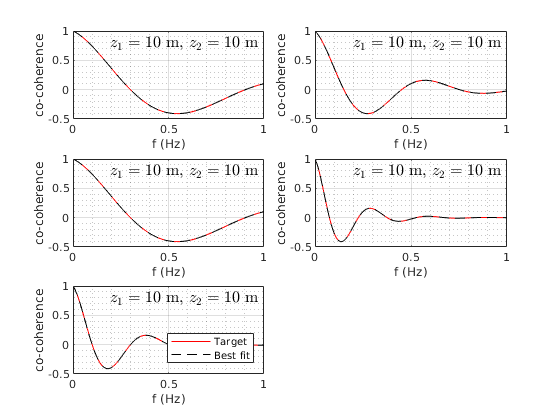



guess = 5;
[CoeffFit,modelFun] = cohFit(dy,f,cohU,guess,meanU,'freqThres',0.2,'dx',dx);
clear leg
clf;close all;
figure
tiledlayout('flow','tilespacing','none')
for ii=1:Nm
    nexttile
    plot(f,cohU(ii,:),'r');hold on;
    plot(f,modelFun(CoeffFit,f,dy(ii),meanZ(ii),meanU(ii),dx(ii)),'k--')
    txt = ['$z_1 = ',num2str(z(indZ(ii,1))),'$ m, $z_2 = ',num2str(z(indZ(ii,2))),'$ m'];
    label(txt,0.97,0.97,'alignement','right','verticalalignment','top');
    grid on
    grid minor
    xlabel('f (Hz)')
    ylabel('co-coherence')
    
end
legend('Target','Best fit','location','southeast')

## Case of time series of velocity fluctuations

In this example, only vertical separation are selected. We do not assume that we know which coherence model fits best. Note, however, that these are simulated wind histories, where the Davenport coherence model was used. In this example, Cuz =  10, Cvz = 10 and Cwz = 3, where Cuz, Cvz an Cwz are the Davenport decay coefficient for the u,v and w components and vertical spatial separation.

clearvars;close all; clc;
load('timeSeries.mat','u','v','w','t','nodes')
U = nanmean(u);
z = nodes.Z;
fs = 1./median(diff(t));
[d,indZ] = getDistance(z); 
% indZ is the indice of unique pairs (the upper triangular elements of the distance matrix)

% Get average height and wind speed
meanZ = zeros(size(indZ,1),1);
meanU = zeros(size(indZ,1),1);
for ii=1:size(indZ,1)
    meanZ(ii) = 0.5.*(z(indZ(ii,1))+z(indZ(ii,2))');
    meanU(ii) = 0.5.*(U(indZ(ii,1))+U(indZ(ii,2))');
end

% Estimate the co-coherence
M = round(numel(t)/20); % 12 blocks
Nm = size(indZ,1);
if mod(M,2)
    cohU = zeros(Nm,round(M/2));
    cohV = zeros(Nm,round(M/2));
    cohW = zeros(Nm,round(M/2));
else
    cohU = zeros(Nm,round(M/2)+1);
    cohV = zeros(Nm,round(M/2)+1);
    cohW = zeros(Nm,round(M/2)+1);
end
for ii = 1:Nm
    u1 = detrend(u(:,indZ(ii,1)));
    u2 = detrend(u(:,indZ(ii,2)));
    [cohU(ii,:),~,f] = coherence(u1,u2,M,round(M/2),M,fs);
    
    v1 = detrend(v(:,indZ(ii,1)));
    v2 = detrend(v(:,indZ(ii,2)));
    [cohV(ii,:),~,f] = coherence(v1,v2,M,round(M/2),M,fs);
    
    w1 = detrend(w(:,indZ(ii,1)));
    w2 = detrend(w(:,indZ(ii,2)));
    [cohW(ii,:),~,f] = coherence(w1,w2,M,round(M/2),M,fs);
end


% We try first the modified Bowen model
guess = [5]; % 2 parameters for the Bowen model
maxFreq = 0.15;
[CoeffFitU,modelFun] = cohFit(d,f,cohU,guess,meanU,'freqThres',maxFreq,'cohModel','Davenport','z',meanZ);
[CoeffFitV,modelFun] = cohFit(d,f,cohV,guess,meanU,'freqThres',maxFreq,'cohModel','Davenport','z',meanZ);
[CoeffFitW,modelFun] = cohFit(d,f,cohW,guess,meanU,'freqThres',maxFreq,'cohModel','Davenport','z',meanZ);

fprintf('Cuz = %1.1f \n',CoeffFitU)

Cuz = 9.9 


fprintf('Cvz = %1.1f \n',CoeffFitV)

Cvz = 10.3 


fprintf('Cwz = %1.1f \n',CoeffFitW)

Cwz = 3.0 


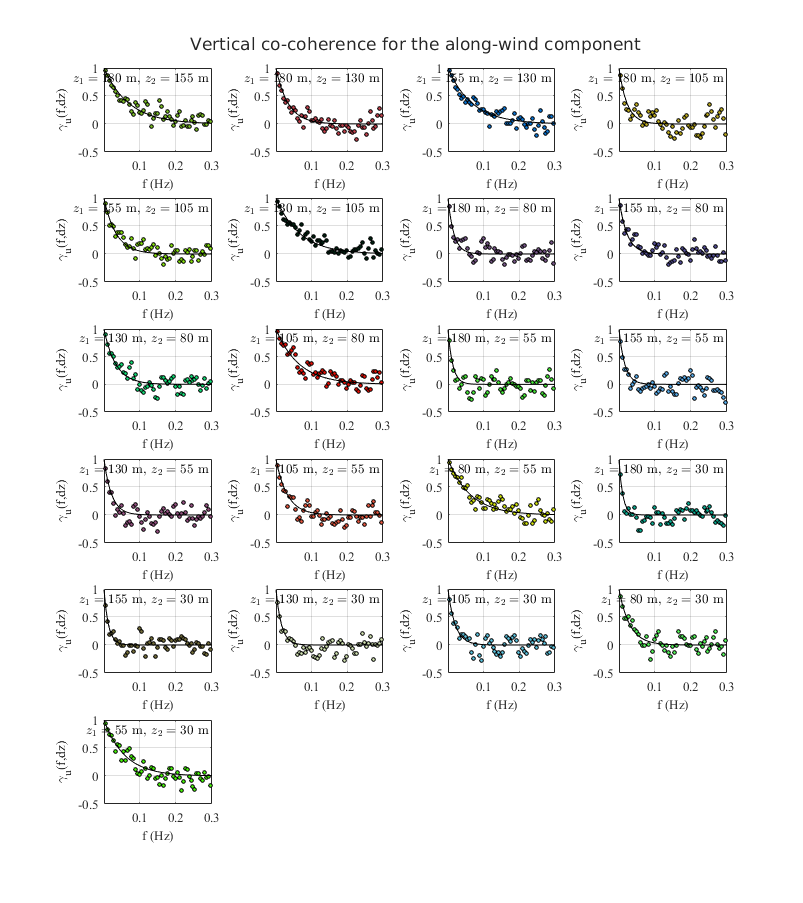


clf;close all;
figure('position',[200          200         803         903])
t1 = tiledlayout('flow','tilespacing','none');
for ii=1:Nm
    nexttile
    plot(f,cohU(ii,:),'ko','markerfacecolor',rand(1,3),'markersize',3);hold on;
    plot(f,modelFun(CoeffFitU,f,d(ii),meanZ(ii),meanU(ii),0),'k')
    txt = ['$z_1 = ',num2str(z(indZ(ii,1))),'$ m, $z_2 = ',num2str(z(indZ(ii,2))),'$ m'];
    label(txt,0.97,0.97,'alignement','right','verticalalignment','top','fontsize',8);
    grid on
    ylim([-0.5,1]);
    xlim([1/t(end), maxFreq*2])
    xlabel('f (Hz)')
    ylabel('\gamma_u(f,dz)')
end
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')
title(t1,'Vertical co-coherence for the along-wind component')

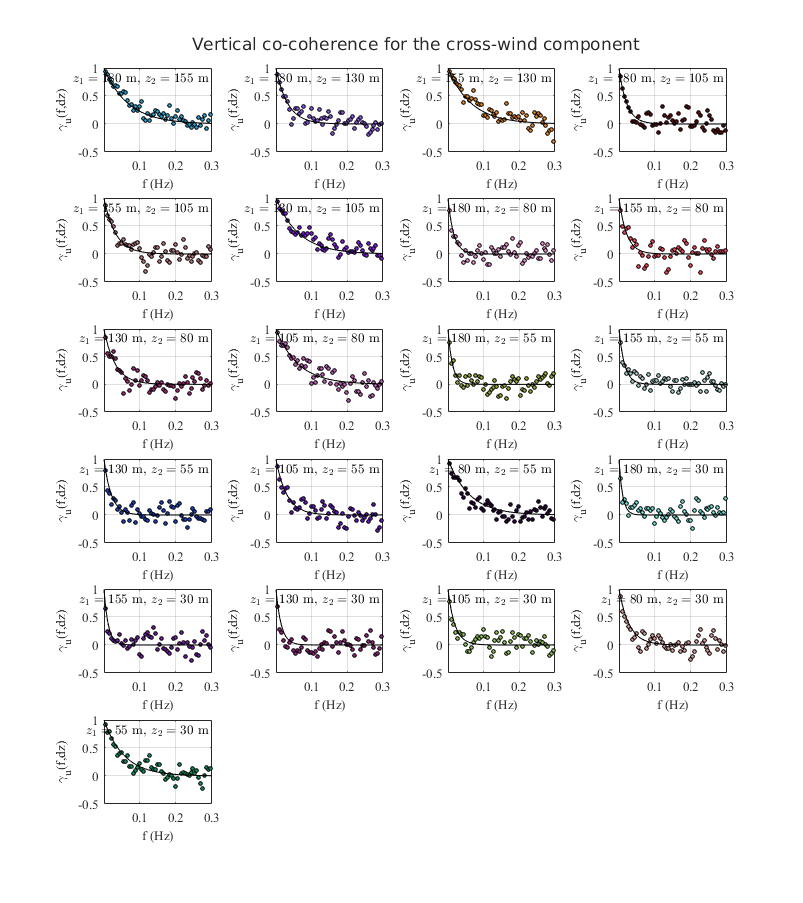



figure('position',[200          200         803         903])
t1 = tiledlayout('flow','tilespacing','none');
for ii=1:Nm
    nexttile
    plot(f,cohV(ii,:),'ko','markerfacecolor',rand(1,3),'markersize',3);hold on;
    plot(f,modelFun(CoeffFitV,f,d(ii),meanZ(ii),meanU(ii),0),'k')
    txt = ['$z_1 = ',num2str(z(indZ(ii,1))),'$ m, $z_2 = ',num2str(z(indZ(ii,2))),'$ m'];
    label(txt,0.97,0.97,'alignement','right','verticalalignment','top','fontsize',8);
    grid on
    ylim([-0.5,1]);
    xlim([1/t(end), maxFreq*2])
    xlabel('f (Hz)')
    ylabel('\gamma_u(f,dz)')
end
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')
title(t1,'Vertical co-coherence for the cross-wind component')

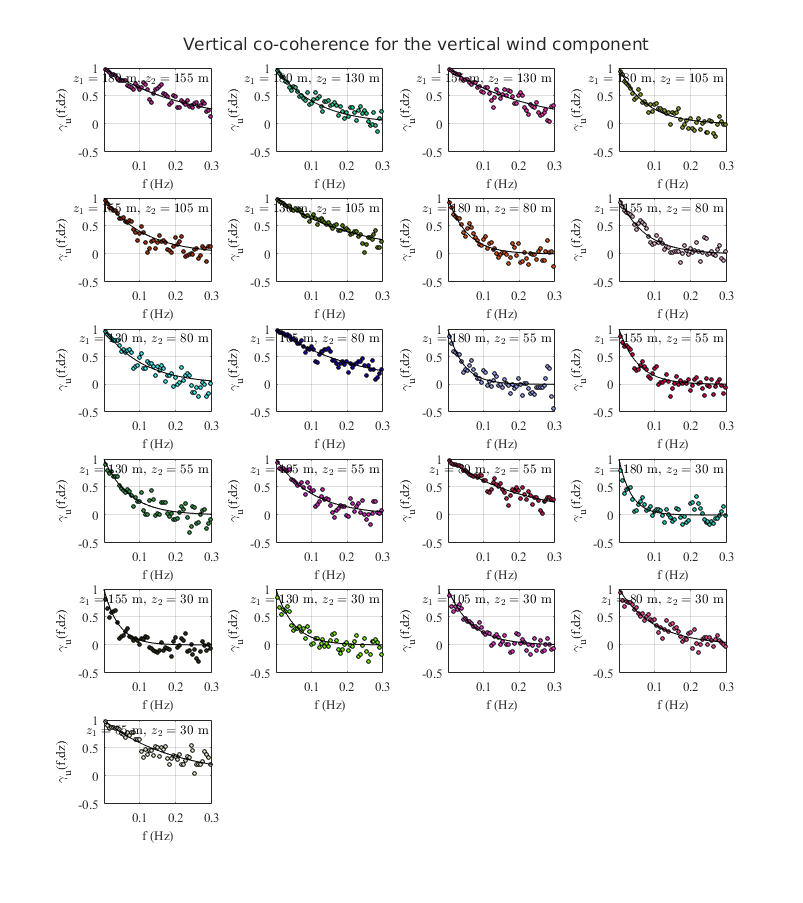


figure('position',[200          200         803         903])
t1 = tiledlayout('flow','tilespacing','none');
for ii=1:Nm
    nexttile
    plot(f,cohW(ii,:),'ko','markerfacecolor',rand(1,3),'markersize',3);hold on;
    plot(f,modelFun(CoeffFitW,f,d(ii),meanZ(ii),meanU(ii),0),'k')
    txt = ['$z_1 = ',num2str(z(indZ(ii,1))),'$ m, $z_2 = ',num2str(z(indZ(ii,2))),'$ m'];
    label(txt,0.97,0.97,'alignement','right','verticalalignment','top','fontsize',8);
    grid on
    ylim([-0.5,1]);
    xlim([1/t(end), maxFreq*2])
    xlabel('f (Hz)')
    ylabel('\gamma_u(f,dz)')
end
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')
title(t1,'Vertical co-coherence for the vertical wind component')